# [Texture Classification](https://apmonitor.com/pds/index.php/Main/TextureClassification)

**Objective**: Use the [**texture classifier**](https://github.com/APMonitor/pds/tree/main/Texture_Classification) to distinguish between sand, seed, and stone and then add an additional texture to the classification (your choice). The script uses a Local Binary Pattern (LBP) to create the features and a [**Support Vector Machine**](https://apmonitor.com/pds/index.php/Main/SupportVectorClassifier) for training and testing.

**Local Binary Pattern**

A Local Binary Patterns (LBP) is a visual descriptor for classification in computer vision by analyzing the local pixels around a point. LBP is an effective feature for texture classification.

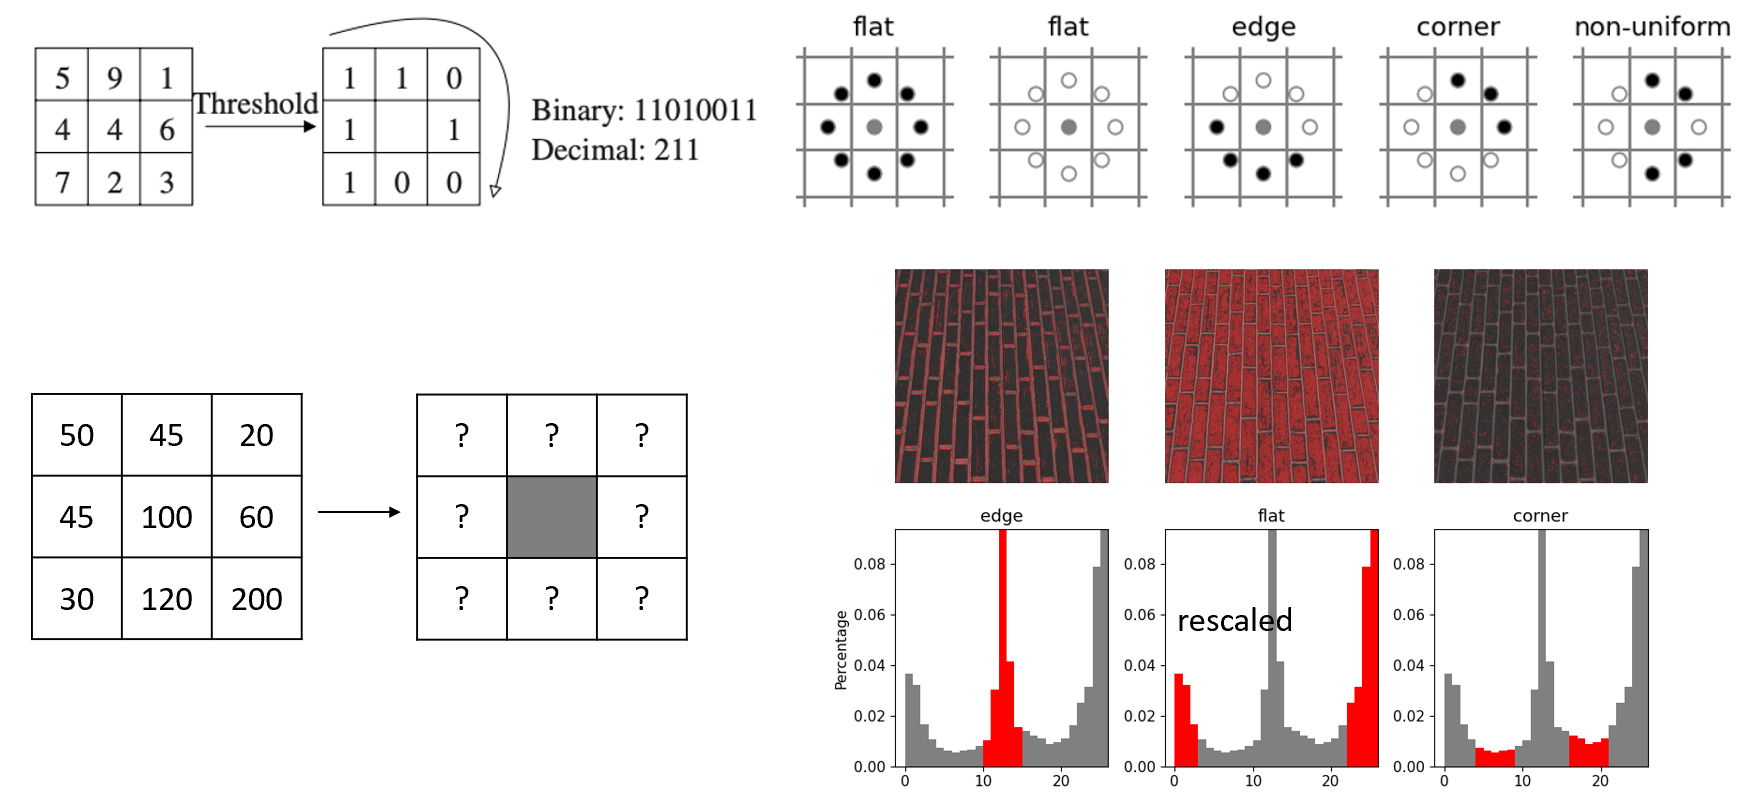

A threshold is set to create a zero or one for each location. The one and zero combinations create a binary pattern that is translated into a decimal. A rotation-invariant transform is performed to create 36 unique patterns.

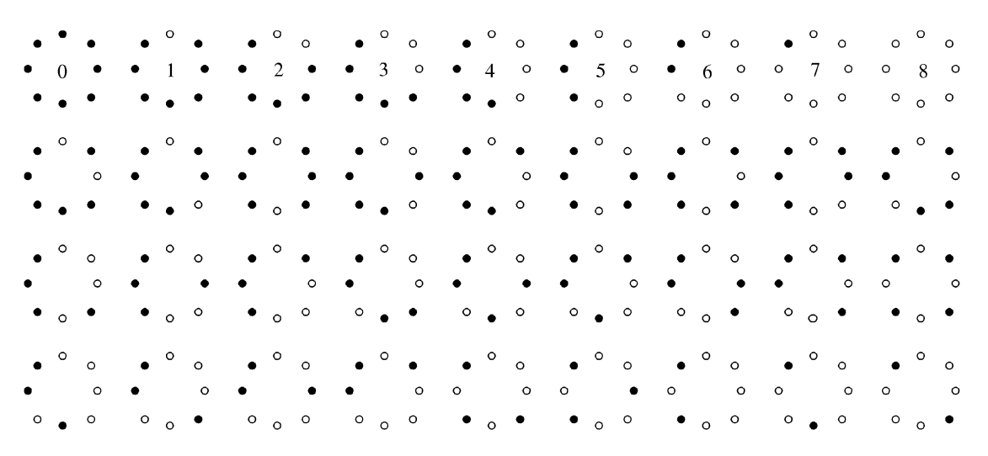

**Train and Test Classifier**

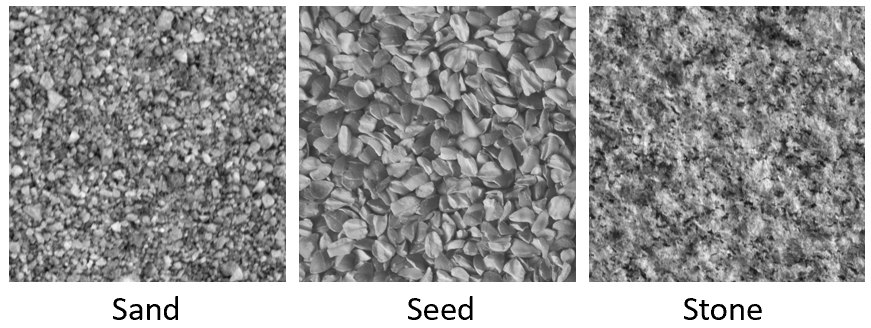

Images of sand, seed, and stone are available in training (*training-set*) and test (*test-set*) folders from the GitHub archive.

[**Texture Classification**](https://github.com/APMonitor/pds/tree/main/Texture_Classification)

The archive includes two source files *step1_LBP.py* and *step2_SVM.py* to analyze the images for the LBP and perform the classification with the SVM. Alternatively, run the exercise down below.

Verify that the following confusion matrix results are obtained when running the scripts. **Tip:** The accuracy with Linear SVC may be improved; try the [**nonlinear SVC**](https://apmonitor.com/pds/index.php/Main/SupportVectorClassifier) or other [**classifiers**](https://apmonitor.com/pds/index.php/Main/ClassificationOverview).

Select a new material such as fabric, grass, wood. Add this texture to add to the training and testing. Create a new folder with 5 new photos in the *test-set* and *training-set* folders. Re-run the programs to determine the new confusion matrix with the added texture. Comment on the accuracy with the new texture.

Another way to detect materials is through Convolutional Neural Networks (CNNs) that use Deep Learning to classify textures and materials. See [**Soil Classification**](https://apmonitor.com/pds/index.php/Main/SoilClassification)

#### Download Photos

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/s3_photos.zip';
filename = 's3_photos.zip';
outfilename = websave(filename,url);

% Unzip then delete zip folder
unzip(outfilename,'./');
delete(outfilename);

#### Load Data

% Load data
train = imageDatastore(['train',filesep], 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train);

test = imageDatastore(['test',filesep], 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
test_preprocess = augmentedImageDatastore([255,255],test);

**List the categories**

labels = unique(string(train.Labels)); % get the unique categories
labels = cellstr(labels);
labels

labels = 3×1 cell array
    {'Sand' }
    {'Seed' }
    {'Stone'}


**Label Encoder**

% Label encoder
le = categorical(train.Labels);
[label_train,~,~] = unique(le);

le = categorical(test.Labels);
label_test = grp2idx(le);

#### Support Vector Machine fit

% Grab the train images and save as an array
numImages = numel(train.Files);
imageArray = zeros(576, 576, numImages, 'uint8');

for i = 1:numImages
    img = readimage(train, i);
    imageArray(:,:,i) = img;
end

% Flatten the matrix
flattenedMatrix = im2double(reshape(imageArray, [], size(imageArray, 3)));

% Train the model
clf = fitcecoc(flattenedMatrix', train.Labels,'Learners','svm');

#### Evaluation

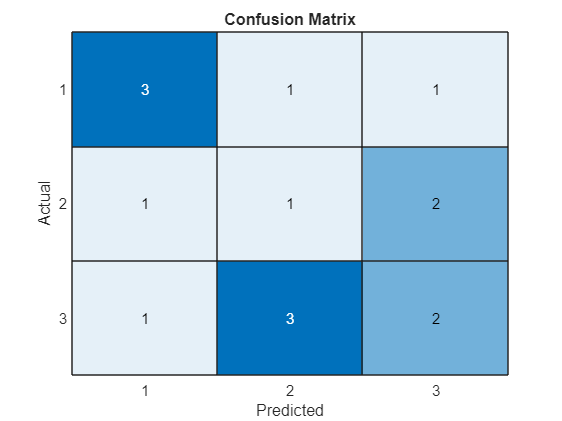

% Grab the images and save as an array
numImages = numel(test.Files);
imageArray = zeros(576, 576, numImages, 'uint8');

for i = 1:numImages
    img = readimage(test, i);
    imageArray(:,:,i) = img;
end

% Flatten the matrix
flattenedMatrix = im2double(reshape(imageArray, [], size(imageArray, 3)));

prediction = predict(clf,flattenedMatrix');

% Visualization
cmat = confusionmat(prediction, test.Labels);
labels = unique(label_test);
figure;
s = heatmap(cmat);
s.Title = 'Confusion Matrix';
s.XLabel = 'Predicted';
s.YLabel = 'Actual';
colorbar off;


% Accuracy calculation
acc = trace(cmat) / sum(cmat(:));
fprintf('Accuracy: %.2f%%\n', acc * 100);

Accuracy: 40.00%
